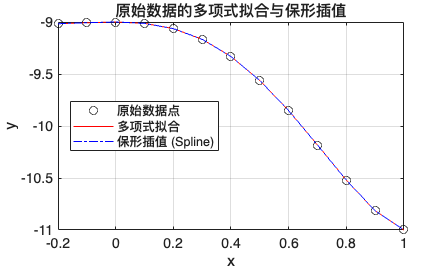

clear all;clc;close all;

x = -0.2:0.1:1;
y_true = 2*x.^5 - 3*x.^3 - x.^2 - 9;
n_points = length(x);
poly_degree = n_points - 1; 
p_fit_orig = polyfit(x, y_true, poly_degree);
y_poly_fit_orig = polyval(p_fit_orig, x);

cs_spline_orig = spline(x, y_true);
y_spline_fit_orig = ppval(cs_spline_orig, x);

figure(1);
plot(x, y_true, 'ko', 'DisplayName', '原始数据点');
hold on;
plot(x, y_poly_fit_orig, 'r-', 'DisplayName', '多项式拟合');
plot(x, y_spline_fit_orig, 'b-.', 'DisplayName', '保形插值 (Spline)');
title('原始数据的多项式拟合与保形插值');
xlabel('x');
ylabel('y');
legend('show', 'Location', 'best');
grid on;
hold off;


disp('--- 第一次拟合 (原始数据) ---');

--- 第一次拟合 (原始数据) ---


disp(['多项式拟合系数 P (降幂): ', num2str(p_fit_orig)]);

多项式拟合系数 P (降幂): 3.0203e-09  -1.478e-08   3.045e-08 -3.4013e-08  2.1868e-08 -7.6254e-09  9.1036e-10           2 -9.4994e-11          -3          -1 -8.3768e-14          -9


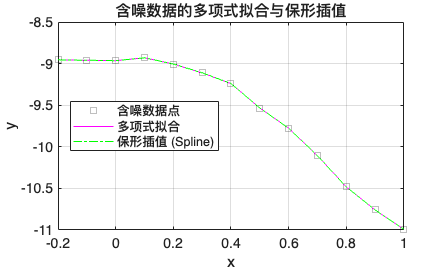




random_noise = 0.1 * rand(1, n_points); 
y_noise = y_true + random_noise; 

p_fit_noise = polyfit(x, y_noise, poly_degree);
y_poly_fit_noise = polyval(p_fit_noise, x);

cs_spline_noise = spline(x, y_noise);
y_spline_fit_noise = ppval(cs_spline_noise, x);

figure(2);
plot(x, y_noise, 'ks', 'DisplayName', '含噪数据点');
hold on;
plot(x, y_poly_fit_noise, 'm-', 'DisplayName', '多项式拟合');
plot(x, y_spline_fit_noise, 'g-.', 'DisplayName', '保形插值 (Spline)');
title('含噪数据的多项式拟合与保形插值');
xlabel('x');
ylabel('y');
legend('show', 'Location', 'best');
grid on;
hold off;


disp(' ');

disp('--- 第二次拟合 (含噪数据) ---');

--- 第二次拟合 (含噪数据) ---


disp(['多项式拟合系数 P_noise (降幂): ', num2str(p_fit_noise)]);

多项式拟合系数 P_noise (降幂): 112349.52269     -530326.05724       1043417.297     -1096574.3602      646329.51799      -193939.3243      11744.378435      9048.8920731     -2112.9679951      40.729708657      21.302459469    -0.95825830376     -8.9648340491


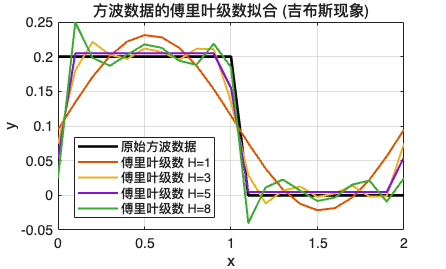


x = 0:0.1:2; % x 轴范围
y_rect = [0.2, 0.2, 0.2, 0.2, 0.2, 0.2, 0.2, 0.2, 0.2, 0.2, 0.2, ...
          0, 0, 0, 0, 0, 0, 0, 0, 0, 0];
N = length(x); % 数据点数量，N = 21
T = x(end) - x(1); 


figure(3);
plot(x, y_rect, 'k-', 'LineWidth', 2, 'DisplayName', '原始方波数据');
hold on;

% 拟合的级数数量
num_harmonics = [1, 3, 5, 8, 15, 30, 50, 100]; 
omega0 = 2*pi/T; 

for h = num_harmonics
    y_fourier = zeros(size(x));
    a0 = mean(y_rect);
    y_fourier = y_fourier + a0;
    for n = 1:2:2*h-1 % n=1, 3, 5, ...
        an = (2/T) * trapz(x, y_rect .* cos(n * omega0 * x)); 
        bn = (2/T) * trapz(x, y_rect .* sin(n * omega0 * x)); 
        y_fourier = y_fourier + an * cos(n * omega0 * x) + bn * sin(n * omega0 * x);
    end
    % 绘制拟合结果
    if ismember(h, [1, 3, 5, 8]) 
        plot(x, y_fourier, 'DisplayName', ['傅里叶级数 H=' num2str(h)], 'LineWidth', 1.5);
    end
end

title('方波数据的傅里叶级数拟合 (吉布斯现象)');
xlabel('x');
ylabel('y');
legend('show', 'Location', 'best');
grid on;
hold off;

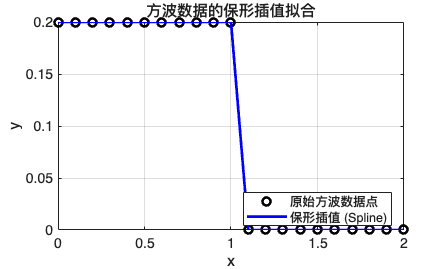

--- 保形插值分析 ---


Spline 曲线穿过所有数据点，但在跳变处 (例如 x=1.0) 曲线非常陡峭，以尝试连接不连续的点，平滑性不如连续函数。



%保形插值拟合,使用样条插值拟合原始数据
cs_spline = spline(x, y_rect);
y_spline = ppval(cs_spline, x);

figure(4);
plot(x, y_rect, 'ko', 'LineWidth', 2, 'DisplayName', '原始方波数据点');
hold on;
plot(x, y_spline, 'b-', 'LineWidth', 2, 'DisplayName', '保形插值 (Spline)');

title('方波数据的保形插值拟合');
xlabel('x');
ylabel('y');
legend('show', 'Location', 'best');
grid on;
hold off;

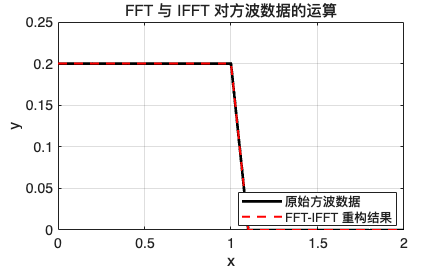

Y_fft = fft(y_rect);
y_ifft = ifft(Y_fft);
figure(5);
plot(x, y_rect, 'k-', 'LineWidth', 2, 'DisplayName', '原始方波数据');
hold on;
plot(x, real(y_ifft), 'r--', 'LineWidth', 1.5, 'DisplayName', 'FFT-IFFT 重构结果');

title('FFT 与 IFFT 对方波数据的运算');
xlabel('x');
ylabel('y');
legend('show', 'Location', 'best');
grid on;
hold off;

%定义f(x) 和 f'(x)
f = @(x) 4*cos(x) - exp(x);
df = @(x) -4*sin(x) - exp(x);

% 2. 定义精度要求和常量
TOL = 1e-4; 
MAX_ITER = 100; % 最大迭代次数
PI = pi;

%二分法 

a = PI/4; % x0 = pi/4
b = PI/2; % x1 = pi/2
iter_bisection = 0;

if f(a) * f(b) > 0
    error('二分法：初始区间 [a, b] 上没有根，f(a) 和 f(b) 必须异号。');
end
x_b = (a + b) / 2; % 初始中点
x_prev = x_b;
for k = 1:MAX_ITER
    iter_bisection = k;
    x_next = (a + b) / 2;
    
    if abs(x_next - x_prev) < TOL
        x_b = x_next;
        break;
    end

    if f(a) * f_next < 0 % 根在 [a, x_next]
        b = x_next;
    else % 根在 [x_next, b]
        a = x_next;
    end
    x_prev = x_next;
end
root_bisection = x_b;
fprintf('二分法结果: 根 x = %.5f, 迭代次数 = %d\n', root_bisection, iter_bisection);

二分法结果: 根 x = 1.17810, 迭代次数 = 1



% 牛顿法
x_n = PI/4; % x0 = pi/4
iter_newton = 0;
for k = 1:MAX_ITER
    iter_newton = k;
    f_val = f(x_n);
    df_val = df(x_n);
    if abs(df_val) < 1e-10 % 避免除以零
        warning('牛顿法：导数过小，可能不收敛或找到极值点。');
        break;
    end
    x_next = x_n - f_val / df_val;
    if abs(x_next - x_n) < TOL
        x_n = x_next;
        break;
    end
    x_n = x_next;
end
root_newton = x_n;
fprintf('牛顿法结果: 根 x = %.5f, 迭代次数 = %d\n', root_newton, iter_newton);

牛顿法结果: 根 x = 0.90479, 迭代次数 = 3



% 割线法 
x0_s = PI/4; % x0 = pi/4
x1_s = PI/2; % x1 = pi/2
iter_secant = 0;

for k = 1:MAX_ITER
    iter_secant = k;
    f0 = f(x0_s);
    f1 = f(x1_s);
    if abs(f1 - f0) < 1e-10 % 避免除以零
        warning('割线法：f(x1) 约等于 f(x0)，可能不收敛。');
        break;
    end
    x_next = x1_s - f1 * (x1_s - x0_s) / (f1 - f0);
    if abs(x_next - x1_s) < TOL
        x1_s = x_next;
        break;
    end
    x0_s = x1_s;
    x1_s = x_next;
end
root_secant = x1_s;
fprintf('割线法结果: 根 x = %.5f, 迭代次数 = %d\n', root_secant, iter_secant);

割线法结果: 根 x = 0.90479, 迭代次数 = 4


% fzero 指令计算
x_initial = [PI/4, PI/2]; % 初始区间 [x0, x1]

% fzero 会自动选择二分法或割线法
options = optimset('Display', 'iter'); 
[root_fzero, fval, exitflag, output] = fzero(f, x_initial);

fprintf('fzero 结果: 根 x = %.5f\n', root_fzero);

fzero 结果: 根 x = 0.90479


fprintf('fzero 迭代次数 (函数评价次数): %d\n', output.funcCount);

fzero 迭代次数 (函数评价次数): 7


fprintf('  1. 二分法迭代次数: %d 次\n', iter_bisection);

  1. 二分法迭代次数: 1 次


fprintf('  2. 牛顿法迭代次数: %d 次\n', iter_newton);

  2. 牛顿法迭代次数: 3 次


fprintf('  3. 割线法迭代次数: %d 次\n', iter_secant);

  3. 割线法迭代次数: 4 次


disp(['  * 最终计算得到的根（精确到小数点后五位）约为: ', sprintf('%.5f', root_newton)]);

  * 最终计算得到的根（精确到小数点后五位）约为: 0.90479


f = @(x) x(1)^2 + 25*x(2)^2 - 2*x(1) + 50*x(2) + 25;

x0 = [2; 3]; 
options = optimset('Display', 'iter');
[x_min, fval_min, exitflag, output] = fminsearch(f, x0, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1              400         
     1            3              400         initial simplex
     2            5          342.572         expand
     3            7          315.113         expand
     4            9          207.235         expand
     5           11           125.44         expand
     6           13          9.46044         expand
     7           15           1.1045         reflect
     8           17           1.1045         contract outside
     9           19           1.1045         contract inside
    10           21           1.1045         contract inside
    11           23           1.1045         contract inside
    12           25           1.1045         contract inside
    13           27          1.09322         reflect
    14           29         0.754544         expand
    15           31          0.46644         expand
    16           33       0.00769218         reflect
    17 


fprintf('初始点: (x0, y0) = (%.2f, %.2f)\n', x0(1), x0(2));

初始点: (x0, y0) = (2.00, 3.00)


fprintf('极小点 x*: (x, y) = (%.4f, %.4f)\n', x_min(1), x_min(2));

极小点 x*: (x, y) = (1.0000, -1.0000)


fprintf('极小值 f(x*): %.4f\n', fval_min);

极小值 f(x*): -1.0000
